Входные параметры

close all;
clear variables;
tic; % замер времени

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = c/f*1000; % 0.75 м %%% убрать 
% /1000/lambda % перевод мм в м + в дилнаях волн

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

% геометрические данные антенны
angle = 65;


#### 1.3. Расчет координат точек исходной фигуры

lambda = 1000;

pl = struct('x', {}, 'y', {});
pl(1).x = 0/lambda;
pl(1).z = 0/lambda;
pl(2).x = 9.3048e+03/lambda;
pl(2).z = 1.9954e+04/lambda;
pl(3).x = 1.4236e+04/lambda;
pl(3).z = 1.9954e+04/lambda;
pl(4).x = 1.4236e+04/lambda;
pl(4).z = 15534/lambda;
pl(5).x = 6992/lambda;
pl(5).z = 0/lambda;

X_point = horzcat(pl(1).x, pl(2).x, pl(3).x, pl(4).x, pl(5).x);
Z_point = horzcat(pl(1).z, pl(2).z, pl(3).z, pl(4).z, pl(5).z);

#### 1.3. Расчет координат точек окружностей

pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});

% begin
pc(1).int1 = [155, 0]/lambda;
pc(1).int2 = [294, 634]/lambda;
pc(1).centr = [1655, 0]/lambda;
pc(1).r = 1500/lambda;

pc(2).int1 = [9170, 19665]/lambda;
pc(2).int2 = [9623, 19954]/lambda;
pc(2).centr = [9623, 19454]/lambda;
pc(2).r = 500/lambda;

pc(3).int1 = [13718, 19954]/lambda;
pc(3).int2 = [14218, 19454]/lambda;
pc(3).centr = [13718, 19454]/lambda;
pc(3).r = 500/lambda;

pc(4).int1 = [14218, 15829]/lambda;
pc(4).int2 = [14077, 15195]/lambda;
pc(4).centr = [12718, 15829]/lambda;
pc(4).r = 1500/lambda;

pc(5).int1 = [7287, 634]/lambda;
pc(5).int2 = [7147, 0]/lambda;
pc(5).centr = [8647, 0]/lambda;
pc(5).r = 1500/lambda;

#### Параметры окружностей

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = acosd( ...
                 (pc(1).centr(1)-pc(1).int2(1)) ...
                  /pc(1).r);
dphi_1 = phi_1_end - phi_1_begin;

% вторая окружность 
phi_2_begin = acosd( ...
                 (pc(2).centr(1)-pc(2).int1(1)) ...
                  /pc(2).r); % относительно оси х
phi_2_end = acosd( ...
                 (pc(2).centr(1)-pc(2).int2(1)) ...
                  /pc(2).r);
dphi_2 = phi_2_end - phi_2_begin;

% третья окружность 
phi_3_begin = acosd( ...
                 (pc(3).centr(1)-pc(3).int1(1)) ...
                  /pc(3).r); % относительно оси х
phi_3_end = acosd( ...
                 (pc(3).centr(1)-pc(3).int2(1)) ...
                  /pc(3).r);
dphi_3 = phi_3_end - phi_3_begin;

% четверта окружность
phi_4_begin = acosd( ...
                 (pc(4).centr(1)-pc(4).int1(1)) ...
                  /pc(4).r); % относительно оси х
phi_4_end = acosd( ...
                 (pc(4).centr(1)-pc(4).int2(1)) ...
                  /pc(4).r);
dphi_4 = abs(phi_4_end - phi_4_begin);

% пятая окружность
phi_5_begin = acosd( ...
                 (pc(5).centr(1)-pc(5).int1(1)) ...
                  /pc(5).r);
phi_5_end = acosd( ...
                 (pc(5).centr(1)-pc(5).int2(1)) ...
                  /pc(5).r);
dphi_5 = abs(phi_5_end - phi_5_begin);


#### Построение окружностей

%%% Построим дугу окружности 1

N1_t = 40;
R1 = pc(1).r;
% угловой шаг окружности
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*i;
    dx1_c(i) = 2*R1*sind(dphi_1/2);
end

x1_c = pc(1).centr(1);
z1_c = pc(1).centr(2);

x12_r = R1*cosd(-t1+180) + x1_c;
z12_r = R1*sind(-t1+180) + z1_c;

% figure;
% plot(x12_r, z12_r,'g')

%%% Построим дугу окружности 2

N2_t = 40;
R2 = pc(2).r;
% угловой шаг окружности
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*i;
    dx2_c(i) = 2*R2*sind(dphi_2/2);
end

x2_c = pc(2).centr(1);
z2_c = pc(2).centr(2);

x34_r = R2*cosd(-t2+180) + x2_c;
z34_r = R2*sind(-t2+180) + z2_c;

% figure;
% plot(x34_r, z34_r,'g')

%%% Построим дугу окружности 3

N3_t = 40;
R3 = pc(3).r;
% угловой шаг окружности
for i = 1 : N3_t
    phid_step = dphi_3/N3_t;
    t3(i) = phi_3_begin + phid_step*i;
    dx3_c(i) = 2*R3*sind(dphi_3/2);
end

x3_c = pc(3).centr(1);
z3_c = pc(3).centr(2);

x56_r = R3*cosd(-t3+180) + x3_c;
z56_r = R3*sind(-t3+180) + z3_c;

% figure;
% plot(x56_r, z56_r,'g')

%%% Построим дугу окружности 4

N4_t = 40;
R4 = pc(4).r;
% угловой шаг окружности
for i = 1 : N4_t
    phid_step = dphi_4/N4_t;
    t4(i) =  phid_step*i;
    dx4_c(i) = 2*R4*sind(dphi_4/2);
end

x4_c = pc(4).centr(1);
z4_c = pc(4).centr(2);

x78_r = R4*cosd(-t4) + x4_c;
z78_r = R4*sind(-t4) + z4_c;

% figure;
% plot(x78_r, z78_r,'g')

%%% Построим дугу окружности 4

N5_t = 40;
R5 = pc(5).r;
% угловой шаг окружности
for i = 1 : N5_t
    phid_step = dphi_5/N5_t;
    t5(i) = 90 + 65 + phid_step*i;
    dx5_c(i) = 2*R5*sind(dphi_5/2);
end

x5_c = pc(5).centr(1);
z5_c = pc(5).centr(2);

x910_r = R5*cosd(t5) + x5_c;
z910_r = R5*sind(t5) + z5_c;

% figure;
% plot(x910_r, z910_r,'g')

#### ОБЩИЙ DX

dx = 

#### Загоним все в массив

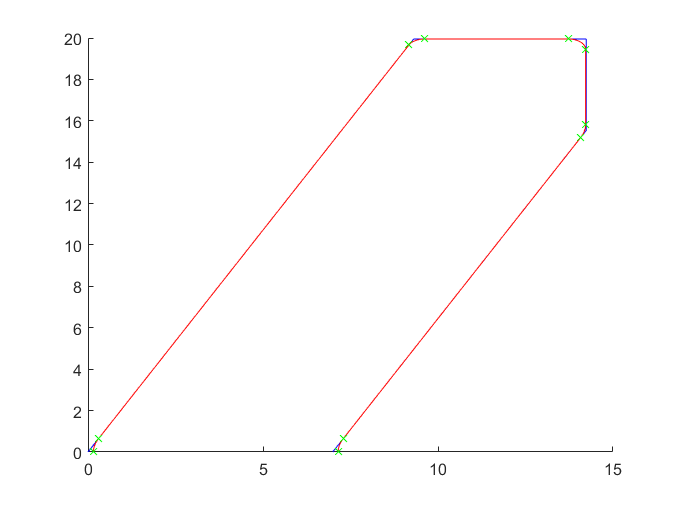

% Порядок точек
x1 = pc(1).int1(1);
x2 = pc(1).int2(1);
x3 = pc(2).int1(1);
x4 = pc(2).int2(1);
x5 = pc(3).int1(1);
x6 = pc(3).int2(1); 
x7 = pc(4).int1(1); 
x8 = pc(4).int2(1);
x9 = pc(5).int1(1); 
x10 = pc(5).int2(1);

z1 = pc(1).int1(2);
z2 = pc(1).int2(2);
z3 = pc(2).int1(2);
z4 = pc(2).int2(2);
z5 = pc(3).int1(2);
z6 = pc(3).int2(2); 
z7 = pc(4).int1(2); 
z8 = pc(4).int2(2);
z9 = pc(5).int1(2); 
z10 = pc(5).int2(2);

% массив крайних точек окружностей
x_temp = [x1,x2,x3,x4,x5,x6,x7,x8,x9,x10];
z_temp = [z1,z2,z3,z4,z5,z6,z7,z8,z9,z10];

% массив точек окружностей
X_r = [x12_r, x34_r, x56_r, x78_r, x910_r];
Z_r = [z12_r, z34_r, z56_r, z78_r, z910_r];
hold on
plot(X_point, Z_point, 'b')
plot(X_r, Z_r, 'r')
plot(x_temp, z_temp, 'gx')
hold off

#### 1.4. Количество точек на антенне

% длины отрезков каждого участков
l23 = sqrt((x2 - x3)^2 + (z2 - z3)^2); 
l45 = sqrt((x4 - x5)^2 + (z4 - z5)^2);
l67 = sqrt((x6 - x7)^2 + (z6 - z7)^2);
l89 = sqrt((x8 - x9)^2 + (z8 - z9)^2);

% точки на окружностях
% N1_t, N2_t, N3_t, N4_t, N5_t

% точки на прямых
N23 = 50;
N45 = N23;
N67 = N23;
N89 = N23;

% cуммареное количество точек на антенне
N = 2*(N23 + N45 + N67 + N89) + 5*N1_t;

#### 2.1 Антена над землей

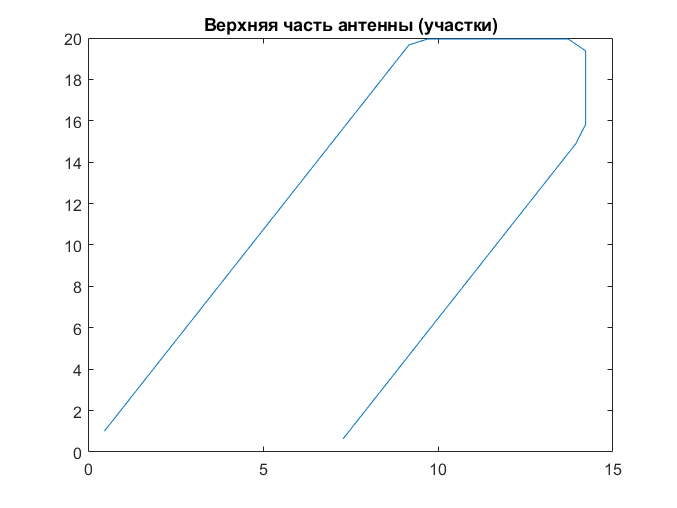

%% УЧАСТОК_1 - наклонный участок
dx_23 = l23/N23;

% заполнение масивов
for i = 1 : N23
    step23 = dx_23*i;
    x23(i) = x2 + cosd(angle)*step23;
    z23(i) = z2 + sind(angle)*step23;
    dx23(i) = dx_23;
end

%% УЧАСТОК 2 - горизонтальный участок
dx_45 = l45/N45;

% заполнение масивов
for i = 1 : N45
    step45 = dx_45*i;
    x45(i) = x4 + step45;
    z45(i) = z4;
    dx45(i) = dx_45;
end

%% УЧАСТОК 3 - вниз
dx_67 = l67/N67;

for i = 1 : N67
    step67 = dx_67*i;
    x67(i) = x6;
    z67(i) = z6 - step67;
    dx67(i) = dx_67;
end

%% УЧАСТОК 4 - наклон вниз
dx_89 = l89/N89;

for i = 1 : N89 
    step89 = dx_89*i;
    x89(i) = x8 - step89*cosd(angle);
    z89(i) = z8 - step89*sind(angle);
    dx89(i) = dx_89;
end

% cклеим все вместе 
X_l = horzcat(x23,x45,x67,x89);
Z_l = horzcat(z23,z45,z67,z89);

figure;
plot(X_l,Z_l)
title("Верхняя часть антенны (участки)")

#### 2.2 Вся антена (границы участков)

% АНТЕННА ПОД ЗЕМЛЕЙ границы участков

X_all = [x12_r, x23, x34_r, x45, x56_r, x67, x78_r, x89, x910_r];
Z_all = [z12_r, z23, z34_r, z45, z56_r, z67, z78_r, z89, z910_r];

Антенная центры участков 

% ПРЯМЫЕ

%% УЧАСТОК_12 - наклонный участок
for i = 1 : N23
    step23 = dx_23*(i-0.5);
    x23_midle(i) = x2 + cosd(angle)*step23;
    z23_midle(i) = z2 + sind(angle)*step23;
end

%% УЧАСТОК 45 - горизонтальный участок
% заполнение масивов
for i = 1 : N45
    step45 = dx_45*(i-0.5);
    x45_midle(i) = x4 + step45;
    z45_midle(i) = z4;
end

%% УЧАСТОК 67 - вниз
for i = 1 : N67
    step67 = dx_67*(i-0.5);
    x67_midle(i) = x6;
    z67_midle(i) = z6 - step67;
end

%% УЧАСТОК 89 - наклон вниз
for i = 1 : N89 
    step89 = dx_89*(i-0.5);
    x89_midle(i) = x8 - step89*cosd(angle);
    z89_midle(i) = z8 - step89*sind(angle);
end

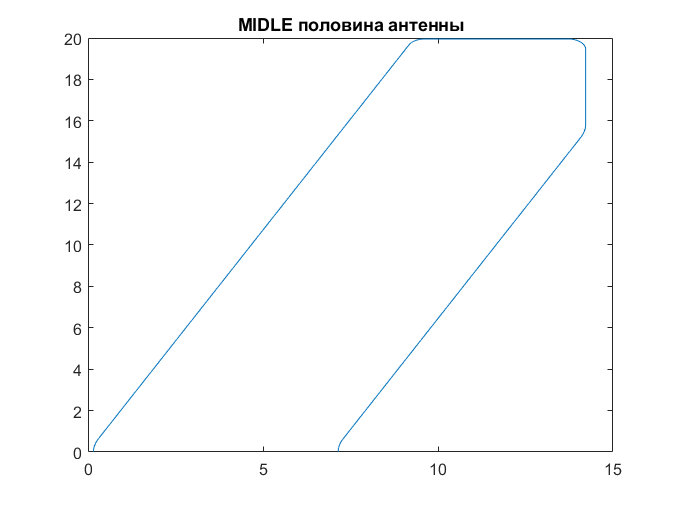

% ОКРУЖНОСТИ

%%% УЧАСТОК 12 - Построим дугу окружности 1
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*(i-0.5);
end

x12_midle = R1*cosd(-t1+180) + x1_c;
z12_midle = R1*sind(-t1+180) + z1_c;

%%% УЧАСТОК 34 - Построим дугу окружности 2
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*(i-0.5);
    dx2_c(i) = 2*R2*sind(dphi_2/2);
end
x34_midle = R2*cosd(-t2+180) + x2_c;
z34_midle = R2*sind(-t2+180) + z2_c;

%%% УЧАСТОК 56 - Построим дугу окружности 3
for i = 1 : N3_t
    phid_step = dphi_3/N3_t;
    t3(i) = phi_3_begin + phid_step*(i-0.5);
end

x56_midle = R3*cosd(-t3+180) + x3_c;
z56_midle = R3*sind(-t3+180) + z3_c;

%%% УЧАСТОК 78 - Построим дугу окружности 4
for i = 1 : N4_t
    phid_step = dphi_4/N4_t;
    t4(i) =  phid_step*(i-0.5);
end
x78_midle = R4*cosd(-t4) + x4_c;
z78_midle = R4*sind(-t4) + z4_c;

%%% УЧАСТОК 910 - Построим дугу окружности 4
for i = 1 : N5_t
    phid_step = dphi_5/N5_t;
    t5(i) = 90 + 65 + phid_step*(i-0.5);
end

x910_midle = R5*cosd(t5) + x5_c;
z910_midle = R5*sind(t5) + z5_c;

% АНТЕННА ПОД ЗЕМЛЕЙ центры участков

x_midle = [x12_midle, x23_midle, x34_midle, x45_midle,...
         x56_midle, x67_midle, x78_midle, x89_midle, x910_midle];
z_midle = [z12_midle, z23_midle, z34_midle, z45_midle,...
         z56_midle, z67_midle, z78_midle, z89_midle, z910_midle];

plot(x_midle, z_midle)
title("MIDLE половина антенны")

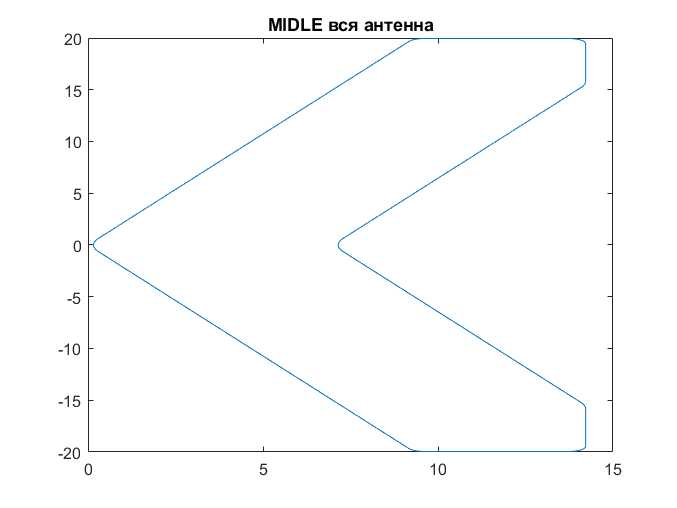


x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z_midle, flip(-z_midle));

plot(x_midle, z_midle)
title("MIDLE вся антенна")

% al_x = 0.96;
% al_z = 0.96;
% 
% X_s = (X_all+2)*al_x - 2*al_x + 0.1;
% Z_s = (Z_all+2)*al_z - 2*al_z;
% 
% figure;
% plot(X_all,Z_all, X_s, Z_s, 'r')
% title("Верхняя часть антенны (участки)")

% сдвиги контуры 
% p = 1;
% 
% % точка 1
% x1_p = p*cosd(25)
% z1_p = 0; 
% 
% % точка 2
% f2=@(x)tand(65)*x - tand(65)*p*cosd(25);
% g2=@(x)pl(2).z - p;
% x2_p = fzero(@(x)f2(x)-g2(x),0.15)
% z2_p = f2(x2_p)
% z2_p = pl(2).z - p;
% 
% % точка 3
% % l_temp = sqrt((pl(2).x - pl(3).x)^2 + (pl(2).z - pl(3).z)^2);
% x3_p = pl(3).x - p;
% z3_p = z2_p;
% 
% % точка 4
% x4_p = x3_p;
% z4_p = tand(65)*x3_p - tand(65)*(pl(5).x - 2*p*sind(25));
% 
% x5_p = pl(5).x - 2*p*sind(25);
% z5_p = 0;
% 
% 
% X_p = [x1_p, x2_p, x3_p, x4_p, x5_p];
% Z_p = [z1_p, z2_p, z3_p, z4_p, z5_p];
% 
% plot(X_all,Z_all, 'b', X_p, Z_p, 'r')
